Koopman 線形化ツール 説明書

📁 パス: \GitHub\common_matlab\Koopman_Linearization

このファイルはKoopman作用素を用いた線形化ツールの全体構造、観測量の設計、処理フローを説明します。

大まかな流れ：

1. データ収集: システム状態と入力の軌跡を取得

2. 観測量定義: phi(x) を設計（非線形写像）

3.★ Koopman 近似: 線形作用素 K を学習

4. ★モデル構築: 未来予測用の線形システム A, B を構成

5. 利用: MPCなどに組み込む

💻　1.　データの収集

Koopman 作用素を近似するには、**系の多様な状態とその時間発展（軌跡）** に関する十分なデータが必要です。

**なぜ「様々な状態の飛行軌跡」が必要か？**

Koopman モデルは「非線形系の状態を高次元に拡張して線形に近似」するための枠組みです。

正確な線形近似を得るには、**多様な初期状態・入力・飛行状況（直進、旋回、降下、上昇など）** に関するデータが欠かせません。

単一の飛行パターンでは、全体の力学的挙動をカバーできず、モデルが偏ります。

データの収集手段

1.モーションキャプチャーを用いて、状態ベクトル x=[x,y,z,ϕ,θ,ψ,vx,vy,vz,ｗϕ,ｗθ,ｗψ]を記録する.広範な軌跡を収集。GUIを利用し、save＿dataボタンを用意。（いわゆる実機データ）

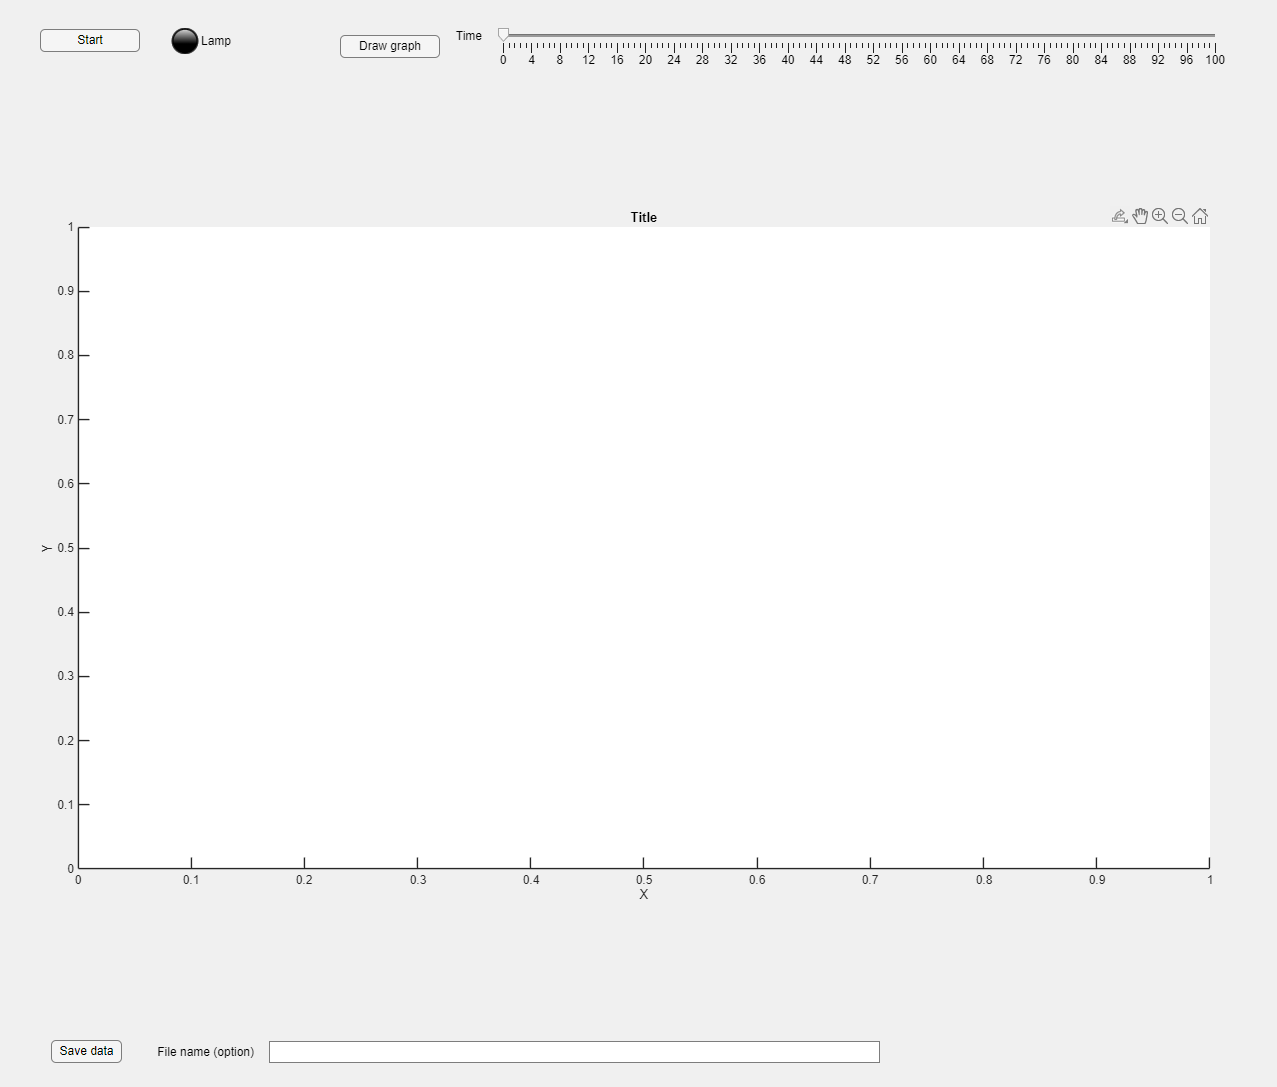

2.数理モデルや物理エンジンに基づく仮想飛行実験を実施。シミュレーション後

logger.save( num2str(j));%ｊは名前（回数）　

を用意（いわゆるシミュレーションデータ）

🧠 2. 観測量の設計 (Observables)

Koopmanの核は、元の状態 x を、拡張された観測量空間 g(x) に写像することです。

非線形システムの状態 x を高次元空間に写像することで、その空間ではシステムの進化を線形として近似できる。この写像がいわゆる「観測量」（observables）、φ(x) と呼ばれる。したがって、φ(x) の設計は Koopman 線形化の効果を左右する。

## なぜ元の状態変数 x だけでは足りないのか？

なぜなら：

元の状態（例えば位置、速度、姿勢角など）は、システムの基本的な挙動しか記述できない。

しかしシステムの**非線形結合項（例えば角度の正弦・余弦、速度と位置の積など）は、動的挙動の中心。

これらの非線形的特徴を含めなければ、Koopman モデルは正しく予測や制御ができない。

% これは線形モデルで非線形現象を捉えるための鍵です。

% 関連ファイル：GitHub\common_matlab\Koopman_Linearization\Koopman_Linear_by_Data\ObservableFunctions
thisFile = matlab.desktop.editor.getActiveFilename;
Rootdir = fileparts(thisFile);
cd(fullfile(Rootdir,'Koopman_Linear_by_Data', 'ObservableFunctions'));
%quaternions_all_00  = 26 observation []

% 📌 追加メモ・図挿入スペース


$$b(\mathbf{x}) = [\mathbf{x}^\top, \; (R_{e_z})^\top, \; 1, \;
\omega_1\omega_2, \; \omega_2\omega_3, \; \omega_3\omega_1, \;\\
\omega_2\cos\phi, \; \omega_3\sin\phi, \;\\
\omega_1\cos\theta / \cos\phi, \;
\omega_2\sin\phi / \cos\phi, \;\\
\omega_3\cos\phi / \cos\phi, \;
\omega_2\sin\phi\sin\theta / \cos\phi, \;\\
\omega_3\cos\phi\sin\theta / \cos\phi]^\top    \in \mathbb{R}^{26}$$


φ(x) の次元が小さすぎると、システムの複雑な力学を正確に捉えることができず、誤差が大きくなる。

しかし、次元が大きすぎると計算コストが高いしたがって、「26個」は 「表現力」と「計算効率」 のバランスが良い折衷案。

 Koopman 近似: 線形作用素 K を学習


$$\mathcal{K}g = g \circ F \quad \Rightarrow \quad \mathcal{K}g(x_k) = g(x_{k+1})$$


`状態 𝑥` `から観測関数 𝜓`(𝑥)`を定義(今は上の26個)`

`拡張状態 𝑧`=𝜓(𝑥) `に対し、線形モデル`$z_{k+1} = \mathcal{K} z_k$`を構築`


$$\mathcal{K} = \underset{\mathcal{K}}{\arg\min} \left\| z_{k+1} - \mathcal{K} z_k \right\|_F^2$$



$$\mathcal{K} = z_{k+1} z'$$


例から見ると、仮に


$$$$
X = [x_1, x_2, \ldots, x_N], \quad X' = [x_2, x_3, \ldots, x_{N+1}]
$$$$



$$$$
\Psi_X = [\psi(x_1), \psi(x_2), \ldots, \psi(x_N)]
$$

$$
\Psi_{X'} = [\psi(x_2), \psi(x_3), \ldots, \psi(x_{N+1})]
$$$$



$$$$
K \approx \Psi_{X'} \Psi_X^{\dagger}
$$$$


% [画像または補足説明をここに挿入]

%% 🧱 2. プログラム構成 (Structure Overview)

% 各ファイルとフォルダの構成：

% - Creating_Datasets.m: 状態を観測量にマップする関数

% - main_KL_ByData_sekiguchi.m: データからKoopman行列を生成

% - `dataset/`, `EstimationResult/`: データの保管場所

%% ⚙️ 4. 分割実行: 観測量の作成

thisFile = matlab.desktop.editor.getActiveFilename;
Rootdir = fileparts(thisFile);
cd(fullfile(Rootdir,'Koopman_Linear_by_Data'));



%% 🧮 1. データのコンパクト
open('Creating_Datasets.m')

13~15行目

データの保存先 datasets 

データの生成はsimxxx.m からには logger.save('aaa') を利用してください。

ただし、controller内ではデータ量が非常に多いため、

一部の obj.result.xx などの情報をコメントアウトする必要があります。

48行目

Data.HowmanyDataset = n;     % 適当に 

50-57行目

setting.vxyz = str2double(input('\n＜速度からx,y,zを算出して学習に使用しますか？＞\n 0:zのみ 1:x,y,zで使用する：','s'));   

データ分析選択肢を選ぶ

setting.datarange = str2double(input([strcat('\n＜使用するデータ範囲を選択してください＞\n', ...

        '1:take off～flight \n', ...

        '2:take off～landing \n', ...

        '3:flight～flight最後 \n', ...

        '4:flight～landing \n', ...

        '5:特定の範囲を設定\n選択された値：')],'s'));

普通は３を選ぶ　以前は、各フライト・ステージに番号を付け、異なる数値フィードバックによってステージ判定する。現在は先生がかわりにPHASEで変更することができるので、ここで手順の変更が必要になるかもしれない。

Data.X = []; Data.Y = []; Data.U = [];

 2. koopman パラメータ生成

open('main_KL_ByData_sekiguchi.m')

gen_hf説明

この関数は、**二次計画問題（Quadratic Programming, QP）** のための行列 H（2次項）とベクトル f（1次項）を生成するものです。主に **Koopman 演算子** を用いたデータ駆動型の状態予測や最適制御に利用されます。以下のような構成になっています：

- 状態 xと制御入力 uを非線形写像（リフト関数） ϕ(x,u)) を通して高次元に写像；

- Koopman モデルによって得られた状態遷移を再現するような最小化問題を構築；